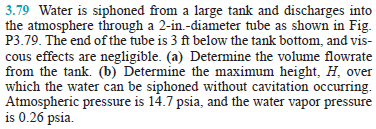

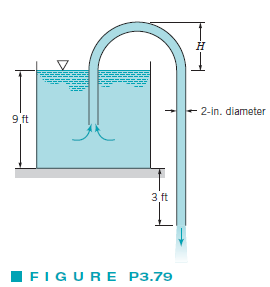

# given

u = symunit;
gamma = 62.4*u.lbf/u.ft^3;
rho = 1.94*u.slug/u.ft^3;
g = 32.2*u.ft/u.s^2;

# part A

% ===============================
% Bernoulli's Equation
% --------------------
p1 = 0;
V1 = 0;
z1 = 12*u.ft;
% --------------------
p2 = 0;
V2 = sym('V2', 'positive');
z2 = 0;
% --------------------
V2 = solve(p1+rho*V1^2/2+gamma*z1 == p2+rho*V2^2/2+gamma*z2);
V2 = simplify(rewrite(V2, u.ft/u.s));
% --------------------
% ===============================
% Continuity equation
D = 2*u.in;
A = sympi*D^2/4;
Q = rewrite(A*V2, u.ft^3/u.s);
% ===============================

# part B

% --------------------
p1b = 14.7*u.psi;
V1b = 0;
z1b = 9*u.ft;
% --------------------
p2b = 0.26*u.psi;
V2b = V2; % by continuity equation
z2b = 9*u.ft+sym('H');
% --------------------
H = solve(p1b+rho*V1b^2/2+gamma*z1b == p2b+rho*V2b^2/2+gamma*z2b);
H = simplify(H);